# Matlab live script for analyzing path integration during ultrasound-evoked escape responses.

You wil require the following files to run this code:

- CSV file created by the DLC (nose, centre and tail x and y points required)

- Bonsai XY file created by Bonsai during testing.

- Ultrasound onset (in seconds) - calculated based on the keystroke timestamps file created by Bonsai during testing.

- Video file used in the DLC.

## Import DLC data

clear all;close all;clc;

[fileName, pathName] = uigetfile('*.csv');
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["scorer", "nose_x", "nose_y", "nose_accuracy", "centre_x", "centre_y", "centre_accuracy", "tail_x", "tail_y", "tail_accuracy", "shelter_x", "shelter_y", "shelter_accuracy"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
azopts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
DLCraw = readtable(fullfile(pathName,fileName),opts)

DLCraw = 29467×13 table
    scorer    nose_x    nose_y    nose_accuracy    centre_x    centre_y    centre_accuracy    tail_x    tail_y    tail_accuracy    shelter_x    shelter_y    shelter_accuracy
    ______    ______    ______    _____________    ________    ________    _______________    ______    ______    _____________    _________    _________    ________________

       0      501.33    515.75             1        545.96      497.59               1         586.2    473.89       0.99997          NaN          NaN             NaN       
       1   

clear opts

## Import Bonsai XY

% import bonsai xy data as a table
[fileName, pathName] = uigetfile('*.csv');

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [4, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["timestampmiliseconds", "x", "y"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
BonsaiXY = readtable(fullfile(pathName,fileName),opts)

BonsaiXY = 29464×3 table
    timestampmiliseconds      x         y   
    ____________________    ______    ______

          4.201e+07          563.5    536.97
          4.201e+07         560.09    537.22
          4.201e+07         559.81    537.43
          4.201e+07         559.99    537.46
          4.201e+07         560.02    537.26
          4.201e+07         122.88    536.72
          4.201e+07         122.87    536.92
          4.201e+07         122.86    536.84
          4.201e+07         559.85    537.38
          4.201e+07         559.96    537.32
         4.2011e+07         559.84    537.35
         4.2011e+07         559.89    537.19
         4.2011e+07         122.87    536.87
         4.2011e+07          563.5       537
         4.2011e+07         559.91    537.39
         4.2011e+07         559.83    537.33


clear opts

BonsaiXY.timestamp = (BonsaiXY.timestampmiliseconds(:,1)-BonsaiXY.timestampmiliseconds(1,1))/1000

BonsaiXY = 29464×4 table
    timestampmiliseconds      x         y       timestamp
    ____________________    ______    ______    _________

          4.201e+07          563.5    536.97           0 
          4.201e+07         560.09    537.22    0.029491 
          4.201e+07         559.81    537.43    0.080243 
          4.201e+07         559.99    537.46      0.1279 
          4.201e+07         560.02    537.26      0.1595 
          4.201e+07         122.88    536.72     0.21048 
          4.201e+07         122.87    536.92     0.24105 
          4.201e+07         122.86    536.84     0.28986 
          4.201e+07         559.85    537.38     0.33853 
          4.201e+07         559.96    537.32     0.36983 
         4.2011e+07         559.84    537.35     0.42072 
         4.2011e+07         559.89    537.19      0.4484 
         4.2011e+07       

### Equalize the Number of Rows from BonsaiXY and DLCraw to combine both files

% Equalize the row numbers.
Min = min([height(BonsaiXY),height(DLCraw)]);
BonsaiXY = BonsaiXY(1:Min,:);DLCraw = DLCraw(1:Min,:);

DLCraw.timestamp = BonsaiXY.timestamp

DLCraw = 29464×14 table
    scorer    nose_x    nose_y    nose_accuracy    centre_x    centre_y    centre_accuracy    tail_x    tail_y    tail_accuracy    shelter_x    shelter_y    shelter_accuracy    timestamp
    ______    ______    ______    _____________    ________    ________    _______________    ______    ______    _____________    _________    _________    ________________    _________

       0      501.33    515.75             1        545.96      497.59               1         586.2    473.89       0.99997 


DLCraw = movevars(DLCraw, 'timestamp', "Before", 'scorer')

DLCraw = 29464×14 table
    timestamp    scorer    nose_x    nose_y    nose_accuracy    centre_x    centre_y    centre_accuracy    tail_x    tail_y    tail_accuracy    shelter_x    shelter_y    shelter_accuracy
    _________    ______    ______    ______    _____________    ________    ________    _______________    ______    ______    _____________    _________    _________    ________________

           0        0      501.33    515.75             1        545.96      497.59               1         586.2    473.89  

## Input the timepoints of ultrasound cue onset

answer = inputdlg('Enter Ultrasound cue onset (in second):','Sample', [1 50]);
ks = str2num(answer{1}); % ks is an array of time points for the ultrasound.

## **Record shelter location information**

% Choose the movie file you used in DLC
[MfileName, MpathName] = uigetfile('*.*');
v = VideoReader(fullfile(MpathName,MfileName));
frame = read(v,900) %frame will be used to define the shelter location

frame = 1074×1128×3 uint8 array
frame(:,:,1) =

     8     8     8     8     8     8     8     8     8     8     8     8     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     8     8     8     8     8     8     8     8     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7     7    

#### Define the shelter boundary

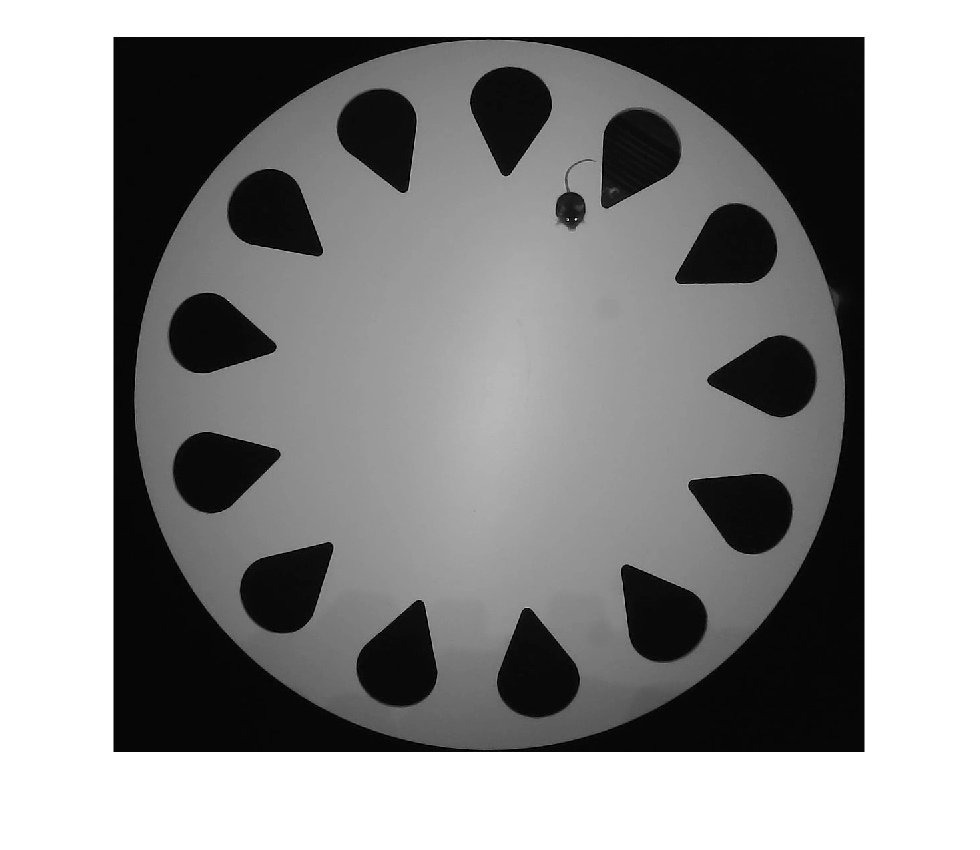

frame = read(v,900); %frame will be used to define the shelter location
imshow(frame);
[shelter_x,shelter_y] = ginput(1); % shelter centre point
ROI = drawcircle('LineWidth',0.5,'StripeColor','cyan','Label','Shelter width');

shelter_r = ROI.Radius; % radius of shelter in pixel.
shelter_d = shelter_r*2

shelter_d = 165.4014

close

## Refine the DLC data

### Fill in missing low accuracy DLC data

acc_threshold = 0.8;
error_noseIDX = find(DLCraw.nose_accuracy < acc_threshold);
DLCraw.nose_x(error_noseIDX) = NaN;
DLCraw.nose_y(error_noseIDX) = NaN;
DLCraw.nose_x = fillmissing(DLCraw.nose_x,"nearest");
DLCraw.nose_y = fillmissing(DLCraw.nose_y,"nearest");

error_tailIDX = find(DLCraw.tail_accuracy < acc_threshold);
DLCraw.tail_x(error_tailIDX) = NaN;
DLCraw.tail_y(error_tailIDX) = NaN;
DLCraw.tail_x = fillmissing(DLCraw.tail_x,"nearest");
DLCraw.tail_y = fillmissing(DLCraw.tail_y,"nearest");

error_centreIDX = find(DLCraw.centre_accuracy < acc_threshold);
DLCraw.centre_x(error_tailIDX) = NaN;
DLCraw.centre_y(error_tailIDX) = NaN;
DLCraw.centre_x = fillmissing(DLCraw.centre_x,"nearest");
DLCraw.centre_y = fillmissing(DLCraw.centre_y,"nearest");

### Create a timetable from the DLC data.

DLCdata = table(DLCraw.nose_x, DLCraw.nose_y,'VariableNames', {'nose_x', 'nose_y'});
DLCdata.centre_x = DLCraw.centre_x;
DLCdata.centre_y = DLCraw.centre_y;
DLCdata.tail_x = DLCraw.tail_x;
DLCdata.tail_y = DLCraw.tail_y;
DLCdata.Time = DLCraw.timestamp;

DLCdata

DLCdata = 29464×7 table
    nose_x    nose_y    centre_x    centre_y    tail_x    tail_y      Time  
    ______    ______    ________    ________    ______    ______    ________

    501.33    515.75     545.96      497.59      586.2    473.89           0
    496.27    513.13      542.9      500.82     580.73    476.76    0.029491
    618.02    379.95     541.14      502.17     579.51    477.08    0.080243
    618.14    380.38     540.53      501.95     579.76    476.28      0.1279
    616.28    380.48      539.6      501.52     482.66    500.13      0.1595
    616.17    380.37     536.64       501.7     482.02    500.05     0.21048
    616.29    380.25     537.03      501.33     481.95    500.51     0.24105
    618.48    380.36     539.57      500.83 

### Add additional features to the timetable

nose = [DLCdata.nose_x DLCdata.nose_y];
tail = [DLCdata.tail_x DLCdata.tail_y];
centre = [DLCdata.centre_x DLCdata.centre_y];
shelter (1:length(nose),1) = shelter_x;
shelter (1:length(nose),2) = shelter_y;

% calculate distance between tail and object(e.g., shelter).
x_t2o = shelter(:,1) - tail(:,1);
y_t2o = shelter(:,2) - tail(:,2);
t2o = sqrt( x_t2o.^2 + y_t2o.^2 );

% calculate distance between tail and nose.
x_t2n = nose(:,1) - tail(:,1);
y_t2n = nose(:,2) - tail(:,2);
t2n = sqrt( x_t2n.^2 + y_t2n.^2 );

% calculate distance between centre and object(e.g., shelter)  -- this is A.
x_c2o = shelter(:,1) - centre(:,1);
y_c2o = shelter(:,2) - centre(:,2);
c2o = sqrt( x_c2o.^2 + y_c2o.^2 );

% calculate distance between centre and nose -- this is B.
x_c2n = nose(:,1) - centre(:,1);
y_c2n = nose(:,2) - centre(:,2);
c2n = sqrt( x_c2n.^2 + y_c2n.^2 );

% calculate distance between nose and object(e.g., shelter) -- this is C.
x_n2o = shelter(:,1) - nose(:,1);
y_n2o = shelter(:,2) - nose(:,2);
n2o = sqrt( x_n2o.^2 + y_n2o.^2 );

% calculate the angle between line a and line b when given the length of connecting line c. cos(theta) = (a^2 + b^2 - c^2)/(2*a*b)
A = c2o;
B = c2n;
C = n2o;
X = (A.^2 + B.^2 - C.^2)./(2.*A.*B);
theta = rad2deg(acos(X)); % the angle column.

% calculate the speed of nose point
clear x y;
v_nose = [];
v_nose(1) = 0;
x = nose(:,1);
y = nose(:,2);
for ii = 2:length(nose)
    v_nose(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_nose = v_nose';

% calculate the speed of centre point
clear x y;
v_centre = [];
v_centre(1) = 0;
x = centre(:,1);
y = centre(:,2);
for ii = 2:length(centre)
    v_centre(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_centre = v_centre';

% calculate the speed of tail point
clear x y;
v_tail = [];
v_tail(1) = 0;
x = tail(:,1);
y = tail(:,2);
for ii = 2:length(tail)
    v_tail(ii) = pdist([x(ii-1) y(ii-1); x(ii) y(ii)], 'euclidean');
end
v_tail = v_tail';

%% v_nose - v_tail may reflect sniffing
diff_v = v_nose - v_tail;

% add new feature columns to the timetable.
DLCdata.n2o = n2o;
DLCdata.t2n = t2n;
DLCdata.t2o = t2o;
DLCdata.c2o = c2o;
DLCdata.c2n = c2n;
DLCdata.theta = theta;
DLCdata.v_nose = v_nose;
DLCdata.v_centre = v_centre;
DLCdata.v_tail = v_tail;
DLCdata.diff_v = diff_v;

% add shelter event columns to the timetable.
event_true = (c2o < shelter_r);
event_dur = [];
for ii = 1:size(event_true,2)
    A = event_true(:,ii);
    out = double(diff([~A(1);A(:)]) == 1);
    v = accumarray(cumsum(out).*A(:)+1,1);
    out(out == 1) = v(2:end);
    event_dur(:,ii) = out;
end
DLCdata.event_true = event_true;
DLCdata.event_dur = event_dur;

% add shelter r, x and y, cue onsets columns.
DLCdata.shelter_r(:) = shelter_r;
DLCdata.shelter_x(:) = shelter_x;
DLCdata.shelter_y(:) = shelter_y;
fps = 1/mean(diff(DLCdata.Time));
DLCdata.fps(:) = fps;

for k = 1:length(ks)
    name = strcat('cueonset',num2str(k));
    DLCdata.(name)(:) = ks(k);
end

DLCdata

DLCdata = 29464×26 table
    nose_x    nose_y    centre_x    centre_y    tail_x    tail_y      Time       n2o       t2n       t2o       c2o       c2n      theta     v_nose     v_centre    v_tail      diff_v      event_true    event_dur    shelter_r    shelter_x    shelter_y     fps      cueonset1    cueonset2    cueonset3
    ______    ______    ________    ________    ______    ______    ________    ______    

## Create trial events around ultrasound cue onsets.

Extract 240 rows for each escape (24 before ultrasound onset, 1 at ultrasound onset and 215 after ultrasound onset).

bl = 24; %number of data points to capture before event onset
seg_dur = 215; %number of data points to capture after event onset

Create a data table for trial events

% clear event_X ndistance distance speed theta tail_x tail_y nose_x nose_y
event_X = {}; % save all event data in a cell array
for k = 1:length(ks)
    temp = find(DLCdata.Time >= ks(k)); %find all data indices that are greater than or equal to keystroke timestamp
    event_X{k} = DLCdata(temp-bl:temp+seg_dur,:);
end

## **Record platform information**

#### Define the platform boundary

frame = read(v,900); %frame will be used to define the shelter location
imshow(frame);
[platform_x,platform_y] = ginput(1);
ROI_platform = drawcircle('LineWidth',0.5,'StripeColor','blue','Label','Platform Zone');
platform_r = ROI_platform.Radius; % radius of roi in pixel.
platform_d = ROI_platform.Radius*2; %diameter of roi in pixles

close

## Correct centre x and centre y data 

### Identify and replace points where DLC had issues tracking by looking centre_x and centre_y data.

centre_x

% fill missing datapoints
for n = 1:length(event_X)
    missingcentre_x = fillmissing(event_X{n}.centre_x,'linear');
    event_X{n}.centre_x = missingcentre_x;
end

% identify centre_x outliers
centre_xoutliers = [];

for k = 1:length(ks)
    centre_xoutliers(:,k) = isoutlier(event_X{k}.centre_x,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalcentre_x =[];
for k = 1:length(ks)
    originalcentre_x(:,k) = event_X{k}.centre_x;
end
close all

% compile corrected DLC tracking data
centre_xcorrected = [];

for k = 1:length(ks)
    centre_xcorrected(:,k) = filloutliers(event_X{k}.centre_x,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

% plot centre_xoutliers
% ERF_time = linspace(-1,9,240);
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
figure
subplot(2,1,1)
plot(ERF_time,centre_xoutliers)
title ('centre_x Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')
hold on
plot(ERF_time,mean(centre_xoutliers,2),'k','LineWidth',5)

centre_y

% fill missing datapoints
for n = 1:length(event_X)
    missingcentre_y = fillmissing(event_X{n}.centre_y,'linear');
    event_X{n}.centre_y = missingcentre_y;
end

% identify centre_y outliers
centre_youtliers = [];

for k = 1:length(ks)
    centre_youtliers(:,k) = isoutlier(event_X{k}.centre_y,"movmedian",[5 5]);
end

% compile original DLC tracking data
originalcentre_y =[];
for k = 1:length(ks)
    originalcentre_y(:,k) = event_X{k}.centre_y;
end
close all

% compile corrected DLC tracking data
centre_ycorrected = [];

for k = 1:length(ks)
    centre_ycorrected(:,k) = filloutliers(event_X{k}.centre_y,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

% plot centre_youtliers
figure
subplot(2,1,1)
plot(ERF_time,centre_youtliers)
title ('centre_y Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')
hold on
plot(ERF_time,mean(centre_youtliers,2),'k','LineWidth',5)

### Plot the corrected centre_x and centre_y data

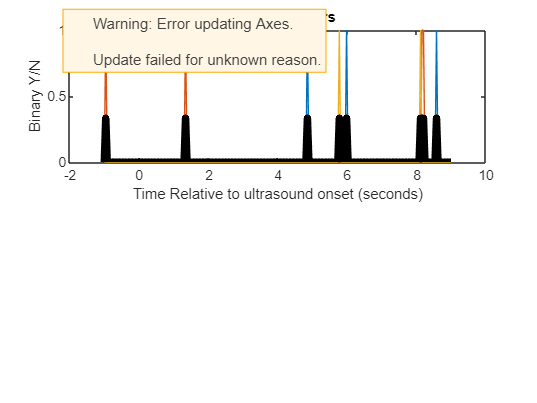

% plot centre_xcorrected
figure
subplot(2,1,1)
plot(ERF_time,centre_xcorrected)
title ('Corrected centre_x')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('X coordinate')

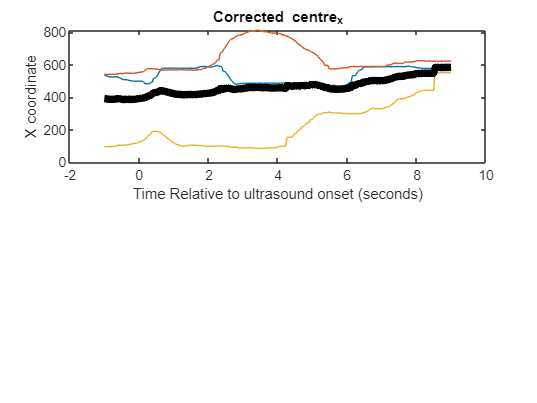

hold on
plot(ERF_time,mean(centre_xcorrected,2),'k','LineWidth',5)

% plot centre_ycorrected
figure
subplot(2,1,1)
plot(ERF_time,centre_ycorrected)
title ('Corrected centre_y')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Y coordinate')
hold on

plot(ERF_time,mean(centre_ycorrected,2),'k','LineWidth',5)

### Update the centre_x and centre_y in the event_X variable

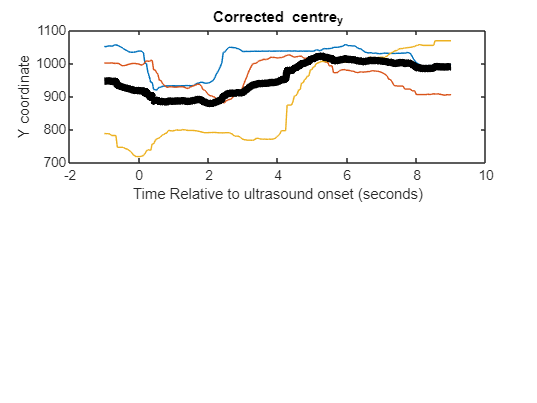

for k = 1:length(ks)
    event_X{k}.centre_x = centre_xcorrected(:,k);
    event_X{k}.centre_y = centre_ycorrected(:,k);
end

for k = 1:length(ks)
    event_X{k}.x_c2o = event_X{k}.shelter_x - event_X{k}.centre_x;
    event_X{k}.y_c2o = event_X{k}.shelter_y - event_X{k}.centre_y;

    event_X{k}.c2o = sqrt(event_X{k}.x_c2o.^2 + event_X{k}.y_c2o.^2);
end

## Distance Data

### Visualize the updated distance from the shelter computed from the corrected centre_x and centre_y

for k = 1:length(ks)
    figure
    subplot(2,1,1)
    plot(ERF_time,event_X{k}.c2o)
    title ('c2o')
    xlabel('Time Relative to ultrasound onset (seconds)')
    ylabel('Distance from shelter')
    hold on
end

### Create distancecorrected variable with the updated distance form the shelter

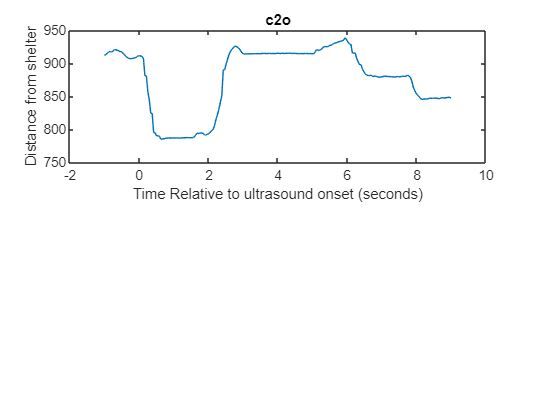

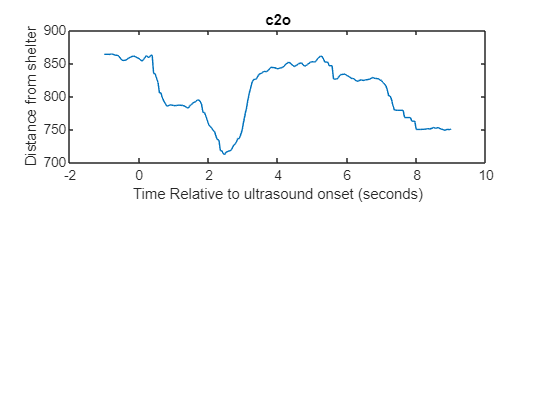

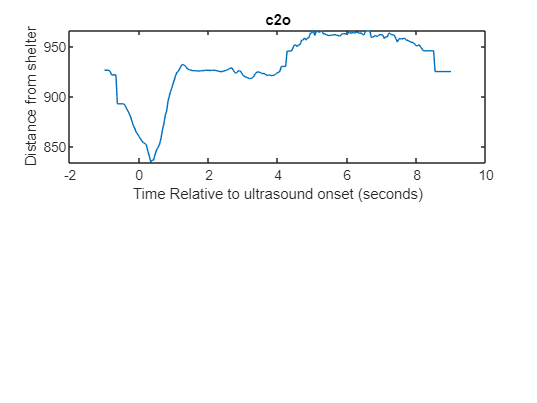

distancecorrected = [];

for k = 1:length(ks)
    distancecorrected(:,k) = event_X{k}.c2o;
end

### Calculate the speed of centre point with corrected centre_x and centre_y data

v_centrecorrected= [];

clear x y;
x = centre_xcorrected(:,:);
y = centre_ycorrected(:,:);

for i = 1:width(centre_xcorrected)
    for ii = 2:length(centre_xcorrected)
        v_centrecorrected(ii,i) = pdist([x(ii-1,i) y(ii-1,i); x(ii,i) y(ii,i)], 'euclidean');
    end
end

v_centrecorrected(1,:) = v_centrecorrected(2,:);

### Update the v_centre in the event_X variable

for k = 1:length(ks);
    event_X{k}.v_centre = v_centrecorrected(1:end,k);
end

### Set head angle, distance and speed to zero upon arrival at the shelter

Identify the rows of the data when the animal is inside the shelter.

% event_true will be 1 when the animal is inside the shelter
correctedevent_true = [];
for k = 1:length(ks)
    correctedevent_true(:,k) = (event_X{k}.c2o < shelter_r);
    event_X{k}.event_true = correctedevent_true(:,k);
end

Identify which trials the animal arrives at the shelter.

Sumofevent_true = [];
for k = 1:length(ks)
    % the Sum of event_true will be 0 if the animal does not arrive at the
    % the Sub of event_true will be > 0 if the animal arrives at the
    % shelter
    Sumofevent_true(:,k) = sum(event_X{k}.event_true);
end

Identify the first row when the animal is inside the shelter.

% If the animal does not arrive at the shelter the last row will be selected
InshelterIndex = [];

for k = 1:length(ks)
    if sum(event_X{k}.event_true) > 1
        InshelterIndex(:,k) = find(event_X{k}.event_true == 1,1,"first");
    elseif sum(event_X{k}.event_true) < 1
        InshelterIndex(:,k) = (length(distancecorrected));
    end
end

Set the distance, head angle, speed, centre_x and centre_y data to 0 after the animal arrives in the shelter

for k = 1:length(ks)
    if InshelterIndex(:,k) < length(distancecorrected);
        event_X{k}.c2o(InshelterIndex(:,k):end) = 0;
        event_X{k}.theta(InshelterIndex(:,k):end) = 0;
        event_X{k}.v_centre(InshelterIndex(:,k):end) = 0;
        event_X{k}.centre_x(InshelterIndex(:,k):end) = shelter_x;
        event_X{k}.centre_y(InshelterIndex(:,k):end) = shelter_y;
    end
end

### Plot final distance data

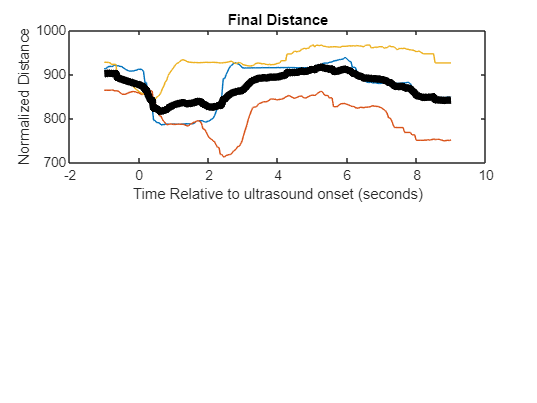

distancefinal = [];
for k = 1:length(ks)
    distancefinal(:,k) = event_X{k}.c2o;
end

figure
subplot(2,1,1)
plot(ERF_time,distancefinal)
title ('Final Distance')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Normalized Distance')
hold on
plot(ERF_time,mean(distancefinal,2),'k','LineWidth',5)

## Speed Data

### Correct speed data

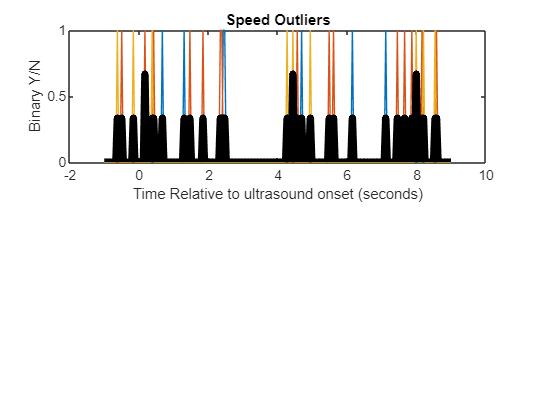

% Fill missing datapoints
for n = 1:length(event_X)
    missingspeed = fillmissing(event_X{n}.v_centre,'linear');
    event_X{n}.v_centre = missingspeed;
end

% Identify speed outliers
speedoutliers = [];

for k = 1:length(ks)
    speedoutliers(:,k) = isoutlier(event_X{k}.v_centre,"movmedian",[5 5]);
end

% Determine how many pixels per m in the video
% The radius of the defined shelter outlined in the video is equilavent to 15.3cm = 0.153m.
% Dividing the shelter radius in pixels by the shelter radius in meters will give you the number of pixels per meter.

% This value depends on the video being analyzed and will change based on
% the identification of the shelter using the drawcircle tool in an earlier code block.
pixelsperm = (shelter_r*2)/0.153; % Ovooid hole
% pixelsperm = (shelter_r*2)/0.05 % Circular hole



% Compile original DLC tracking data
% Here we are dividing by pixelsperm to get speed in m/s instead of pixels/s
originalspeed =[];
for k = 1:length(ks)
    originalspeed(:,k) = event_X{k}.v_centre;
end

% Compile corrected DLC tracking data
speedcorrected = [];

for k = 1:length(ks)
    speedcorrected(:,k) = filloutliers(event_X{k}.v_centre,'linear', "movmedian" ,[5 5]);
    % Speed is divided by pixelsperm to convert from pixels/sec to m/sec
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end

% Plot speed outliers
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
figure
subplot(2,1,1)
plot(ERF_time,speedoutliers)
title ('Speed Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')
hold on
plot(ERF_time,mean(speedoutliers,2),'k','LineWidth',5)

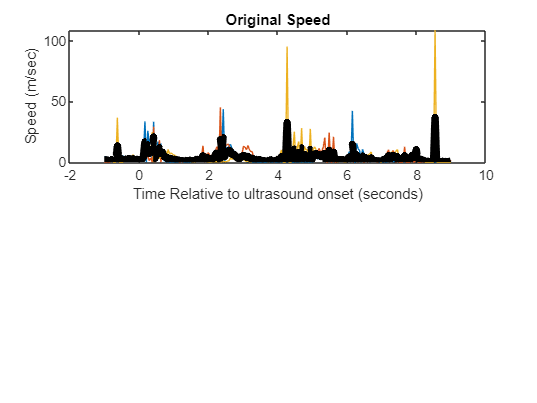


% Plot original speed
figure
subplot(2,1,1)
plot(ERF_time,originalspeed)
title ('Original Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(originalspeed,2),'k','LineWidth',5)

### **Plot speed corrected data**

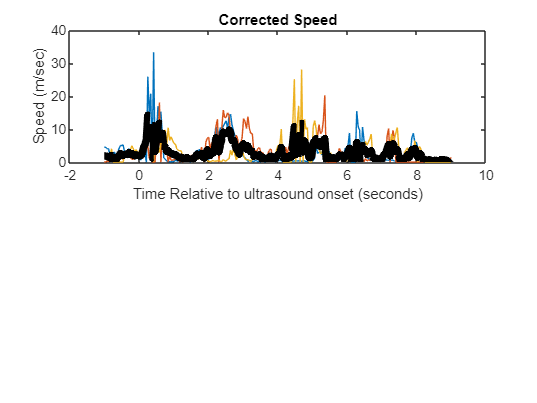

figure
subplot(2,1,1)
plot(ERF_time,speedcorrected)
title ('Corrected Speed')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(speedcorrected,2),'k','LineWidth',5)

Save speed data converted in meters/sec

% divide the width of the shelter hole by length in meters to get pixels per meters
speedmeterspersec =[];
for k = 1:length(ks)
    speedmeterspersec(:,k) = speedcorrected(:,k)/pixelsperm;
end

### **Update event trial data with corrected speed data**

%Replace the speed data in the event_X variable with the speed corrected data
for k = 1:length(ks)
    event_X{k}.v_centre = speedmeterspersec(:,k);
end

## Head Angle Data

### Correct head angle data

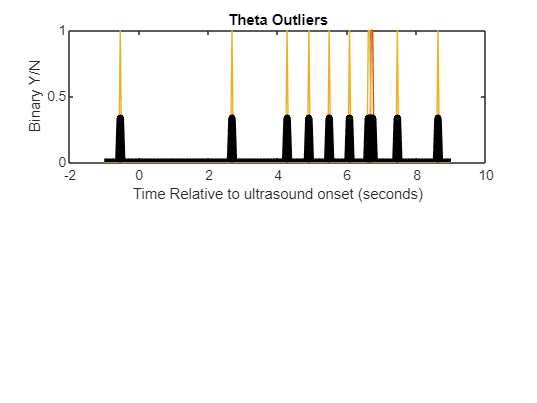

% fill missing datapoints
for n = 1:length(event_X)
    missingtheta = fillmissing(event_X{n}.theta,'linear');
    event_X{n}.theta = missingtheta;
end

% identify theta outliers
thetaoutliers = [];

for k = 1:length(ks)
    thetaoutliers(:,k) = isoutlier(event_X{k}.theta,"movmedian",[5 5]);
end

% compile original DLC tracking data
originaltheta =[];
for k = 1:length(ks)
    originaltheta(:,k) = event_X{k}.theta;
end
close all

% compile corrected DLC tracking data
thetacorrected = [];

for k = 1:length(ks)
    thetacorrected(:,k) = filloutliers(event_X{k}.theta,'linear', "movmedian" ,[5 5]);
    % "linear" - Outliers are filled by linear interpolation of neighboring, nonoutlier values
    % "movmedian" - Outliers are defined as elements more than three local scaled median absolute deviations from the local median over a window length specified by window.
    % This method is also known as a Hampel filter.
end
close all

% Plot head angle outliers
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));
figure
subplot(2,1,1)
plot(ERF_time,thetaoutliers)
title ('Theta Outliers')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Binary Y/N')
hold on
plot(ERF_time,mean(thetaoutliers,2),'k','LineWidth',5)

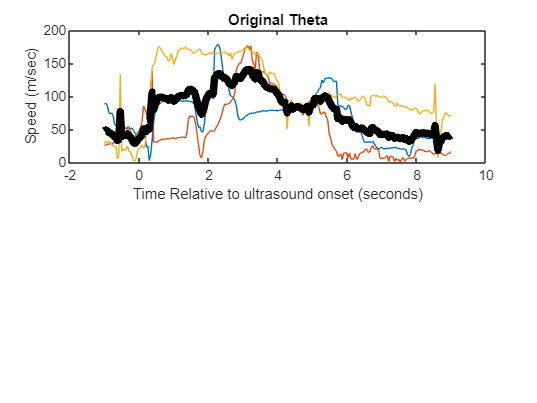


% Plot original head angle
figure
subplot(2,1,1)
plot(ERF_time,originaltheta)
title ('Original Theta')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Speed (m/sec)')
hold on
plot(ERF_time,mean(originaltheta,2),'k','LineWidth',5)

### **Plot theta corrected data**

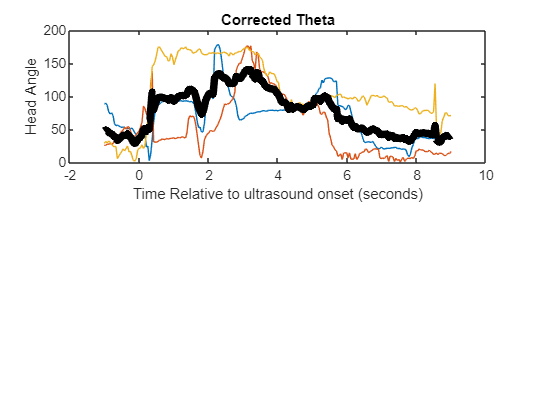

figure
subplot(2,1,1)
plot(ERF_time,thetacorrected)
title ('Corrected Theta')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Head Angle')
hold on
plot(ERF_time,mean(thetacorrected,2),'k','LineWidth',5)

### **Update event trial data with corrected theta data**

%Replace the theta data in the event_X variable with the theta corrected data
for k = 1:length(ks)
    event_X{k}.theta = thetacorrected(:,k);
end

## Plot datapoints around ultrasound cue onsets 

Timeseries data and rasterplots

% Create new variables
speed = [];theta = [];tail_x = [];tail_y = [];nose_x = [];nose_y = [];centre_x =[];centre_y =[]; maxDistance = []; distance = [], ndistance = [];


distance =

     []



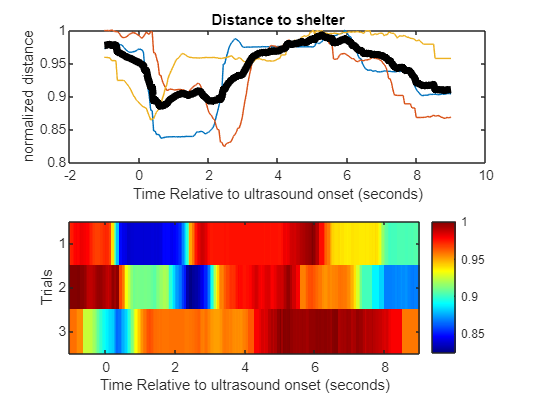


for k = 1:length(ks)
    speed(:,k) = speedcorrected(:,k); theta(:,k) = thetacorrected(:,k); distance(:,k) = distancefinal(:,k); maxDistance(:,k) = max(event_X{k}.c2o); ndistance(:,k) = distancefinal(:,k)/maxDistance(:,k);
    tail_x(:,k) = event_X{k}.tail_x;tail_y(:,k) = event_X{k}.tail_y; nose_x(:,k) = event_X{k}.nose_x;nose_y(:,k) = event_X{k}.nose_y;
    centre_x(:,k) = event_X{k}.centre_x;centre_y(:,k) = event_X{k}.centre_y;
end

close all

% Plot final normalized distance from shelter
figure
subplot(2,1,1)
plot(ERF_time,ndistance)
title ('Distance to shelter')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('normalized distance')
hold on
plot(ERF_time,mean(ndistance,2),'k','LineWidth',5)

subplot(2,1,2)
imagesc(ERF_time,1:length(ks),ndistance')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar

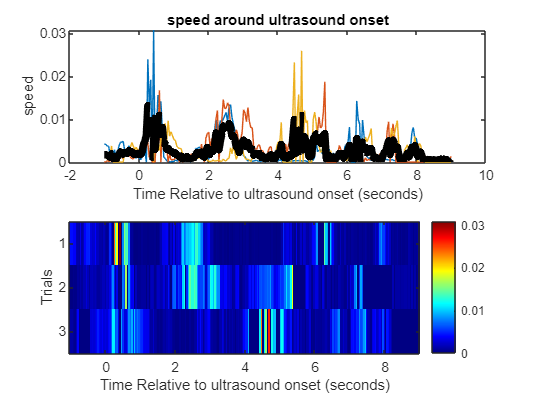


% Plot final speed 
figure
subplot(2,1,1)
plot(ERF_time,speedmeterspersec)
title ('speed around ultrasound onset')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('speed')
hold on
plot(ERF_time,mean(speedmeterspersec,2),'k','LineWidth',5)

subplot(2,1,2)
imagesc(ERF_time,1:length(ks),speedmeterspersec')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar

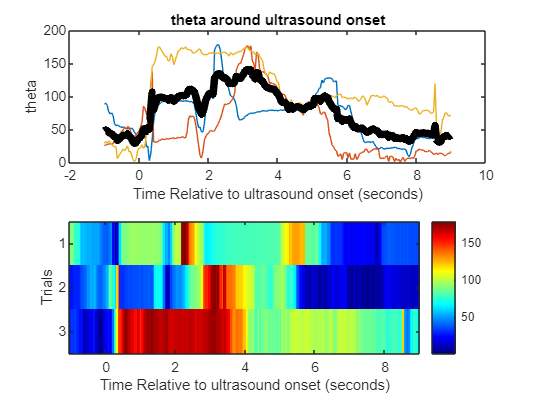

figure
subplot(2,1,1)

% Plot head angle 
plot(ERF_time,thetacorrected)
title ('theta around ultrasound onset')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('theta')
hold on
plot(ERF_time,mean(thetacorrected,2),'k','LineWidth',5)

subplot(2,1,2)
imagesc(ERF_time,1:length(ks),thetacorrected')
xlabel('Time Relative to ultrasound onset (seconds)')
ylabel('Trials')
colormap jet
colorbar

## Condense timeseries data into 1sec bins

### Normalized Distance Binned Data (10 bins)

binnedndistance = [];
for k = 1:length(ks)
    %Bin 1 sec before ultrasound
    binnedndistance(1:1,k) = mean(ndistance(1:24,k));
    % Bin 1 sec after ultrasound
    binnedndistance(2:2,k) = mean(ndistance(25:48,k));
    % Bin 2 sec after ultrasound
    binnedndistance(3:3,k) = mean(ndistance(49:72,k));
    % Bin 3 sec after ultrasound
    binnedndistance(4:4,k) = mean(ndistance(73:96,k));
    % Bin 4 sec after ultrasound
    binnedndistance(5:5,k) = mean(ndistance(97:120,k));
    % Bin 5 sec after ultrasound
    binnedndistance(6:6,k) = mean(ndistance(121:144,k));
    % Bin 6 sec after ultrasound
    binnedndistance(7:7,k) = mean(ndistance(145:168,k));
    % Bin 7 sec after ultrasound
    binnedndistance(8:8,k) = mean(ndistance(169:192,k));
    % Bin 8 sec after ultrasound
    binnedndistance(9:9,k) = mean(ndistance(193:216,k));
    % Bin 9 sec after ultrasound
    binnedndistance(10:10,k) = mean(ndistance(217:240,k));
end

Binned_Time = [1:10];

### Speed Binned Data (10 bins)

binnedspeed = [];

for k = 1:length(ks)
    %Bin 1 sec before ultrasound
    binnedspeed(1:1,k) = mean(speed(1:24,k));
    % Bin 1 sec after ultrasound
    binnedspeed(2:2,k) = mean(speed(25:48,k));
    % Bin 2 sec after ultrasound
    binnedspeed(3:3,k) = mean(speed(49:72,k));
    % Bin 3 sec after ultrasound
    binnedspeed(4:4,k) = mean(speed(73:96,k));
    % Bin 4 sec after ultrasound
    binnedspeed(5:5,k) = mean(speed(97:120,k));
    % Bin 5 sec after ultrasound
    binnedspeed(6:6,k) = mean(speed(121:144,k));
    % Bin 6 sec after ultrasound
    binnedspeed(7:7,k) = mean(speed(145:168,k));
    % Bin 7 sec after ultrasound
    binnedspeed(8:8,k) = mean(speed(169:192,k));
    % Bin 8 sec after ultrasound
    binnedspeed(9:9,k) = mean(speed(193:216,k));
    % Bin 9 sec after ultrasound
    binnedspeed(10:10,k) = mean(speed(217:240,k));
end

Binned_Time = [1:10];

### Theta Binned Data (10 bins)

binnedtheta = [];
for k = 1:length(ks)
    %Bin 1 sec before ultrasound
    binnedtheta(1:1,k) = mean(theta(1:24,k));
    % Bin 1 sec after ultrasound
    binnedtheta(2:2,k) = mean(theta(25:48,k));
    % Bin 2 sec after ultrasound
    binnedtheta(3:3,k) = mean(theta(49:72,k));
    % Bin 3 sec after ultrasound
    binnedtheta(4:4,k) = mean(theta(73:96,k));
    % Bin 4 sec after ultrasound
    binnedtheta(5:5,k) = mean(theta(97:120,k));
    % Bin 5 sec after ultrasound
    binnedtheta(6:6,k) = mean(theta(121:144,k));
    % Bin 6 sec after ultrasound
    binnedtheta(7:7,k) = mean(theta(145:168,k));
    % Bin 7 sec after ultrasound
    binnedtheta(8:8,k) = mean(theta(169:192,k));
    % Bin 8 sec after ultrasound
    binnedtheta(9:9,k) = mean(theta(193:216,k));
    % Bin 9 sec after ultrasound
    binnedtheta(10:10,k) = mean(theta(217:240,k));
end

Binned_Time = [1:10];

## Analyze escape data

### Create new escape data variables

departure_time = [];arrival_time = [];escape_duration = [];arrivalIndex = [];max_time = [];max_speed = [];max_elapsed = [];
escape_distance = []; escape_linearity = []; escape_linearity2 = []; linear_distance = []; linear_distancemeters = []; escape_accuracy = [];
x_linear = []; y_linear = []; escape_distancetravelled =[]; escape_distancemeters = [];

% Create new variables that correspond to data for the 9s ultrasound
% removing the 1s before ultrasound
ERF_time = linspace(-bl/fps,seg_dur/fps,length(event_X{1}.c2o));

ERF_time9s = ERF_time(1, 25:end);
thetacorrected9s = thetacorrected(25:end,:);

ERF_timetranspose = ERF_time';
speedmeterspersec9s = speedmeterspersec(25:end,:);

Duration

We are selecting the row of the timestamp data that corresponds to the first row when the animal is inside the shelter (InshelterIndex).

%Replace the speed data in the event_X variable with the speed
%corrected data
for k = 1:length(ks);
    event_X{k}.Time = ERF_timetranspose;
end

%Identify time from the ultrasound onset when the animal arrived at theshelter
for n = 1:length(event_X);
    arrival_time(n) = (event_X{n}.Time(InshelterIndex(n))); % find the time of arrival
    if arrival_time(n) > 9
        arrival_time(n) = 9
    end
end

Accuracy

For animals that do not arrive at the shelter we are computing a 10% decrease in accuracy when the animal is the diameter of the shelter away from the shelter zone.

For animals that arrive at the shelter before the end of the 9s the accuracy is set to 100%.

for n = 1:length(event_X)
    if   InshelterIndex(n) == (length(distance)); %InshelterIndex(n) == (length(distancefinal));
        escape_accuracy(n) = 100 - 10 * round((event_X{n}.c2o(end)./(2*shelter_r)));
    else escape_accuracy(n) = 100;
    end
    if escape_accuracy(n) < 0
        escape_accuracy(n) = 0
    end
end

Distance

Compute the linear distance between centre and shelter at ultrasound onset

for n = 1:length(event_X);
    linear_distance(n) = event_X{n}.c2o(bl+1); %linear distance between centre point and shelter centre at event onset
end

Distance covered throuhg the 9s ultrasound

Compute the total distance travelled between centre_x and centre_y points

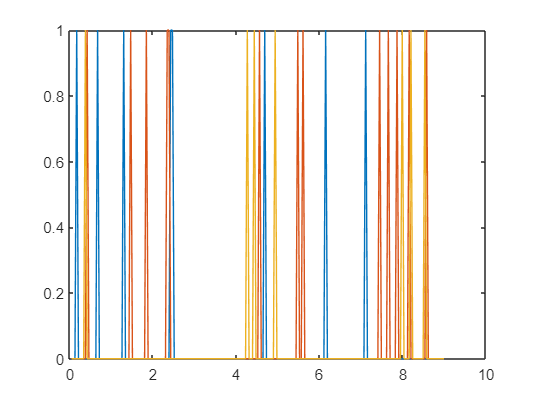

centre_xcorrected = [];
centre_ycorrected = [];

%create new centre_xcorrected and centre_ycorrected variables since the centre_x
%and centre_y variables were set to shelter after arrival at the shelter.
for k = 1:length(ks)
centre_xcorrected(:,k) = event_X{k}.centre_x;
centre_ycorrected(:,k) = event_X{k}.centre_y;
end

% Create new variables for centre_x and centre_y corresponding to the 9s ultrasound removing the 1s
% before the ultrasound 
centre_xcorrected9sec = centre_xcorrected(25:end,:);
centre_ycorrected9sec = centre_ycorrected(25:end,:);

% Distance between centre_x and centre_y points computed as a hypotenus
d = hypot(diff(centre_xcorrected9sec), diff(centre_ycorrected9sec)); %distance of each segment                       

% Correcting any errors
doutlier = isoutlier(d,"movmedian",[5 5]);
ERF_time9s_doutlier = ERF_time9s(2:end);
figure
plot(ERF_time9s_doutlier, doutlier);

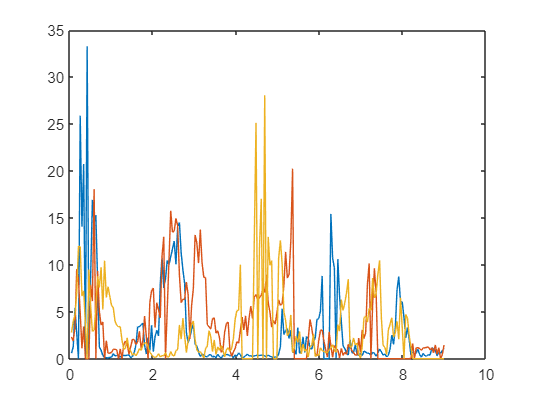


dcorrected = filloutliers(d,"linear", "movmedian",[5 5]);
figure
plot(ERF_time9s_doutlier,dcorrected);


% Total distance travelled across rows throughout the 9s ultrasound
escape_distance = sum(dcorrected);
escape_distancemeters = escape_distance/pixelsperm;

Linearity

Compute the ratio of linear distance between position at ultrasound onset to the distance travelled during escape

We computed the linearity only for trials that were successful. This is because in trials where animals were unsuccessful the distance travelled in the 9s may be less than their distance from the shelter at ultrasound onset.

for n = 1:length(event_X)
    if escape_accuracy(n) < 100
        escape_linearity(n) = NaN;
    else
        escape_linearity(n) = linear_distance(n)/escape_distance(n);
    end
end

Speed

Compute the maximum speed during teach trial, identify the time of maximum speed, identify the head angle at the maximum speed

% find row index and value at the max speed during the 9s.
% M_data represents speed data and I_data represents row number.
[M_data,I_data] = max(speedmeterspersec9s);
max_speed = M_data; % find the max speed in meters/sec
max_elapsed = (ERF_time9s(I_data)); % find the time after ultrasound onset when speed is max.
finalvaluematrix = thetacorrected9s(I_data,1:width(thetacorrected9s)); %
max_theta = transpose(diag(finalvaluematrix)); %find the theta a maximum speed

#### Compile the escape data into one variable and export to csv

Not absolutly necessary to export the data if we are saving the MATLAB file

clear escape
escape.accuracy = escape_accuracy; % 100 - 10 * (distance from end position to the shelter / shelter diameter)
escape.duration = round(arrival_time,2);  % arrival_time - departure_time
escape.distance = round(escape_distancemeters,2); % distance taken from cueonset point to the shelter arrival.
escape.linearity = round(escape_linearity,2); % ratio btw linear distance and travel distance
escape.max_speed = max_speed; % peak speed of escape run
escape.max_elapsed = max_elapsed; % elapsed time from cueonset to peak speed
escape.max_theta = round(max_theta,2); % head angle at max speed

escape

escape = struct with fields:
       accuracy: [50 50 40]
       duration: [8.9900 8.9900 8.9900]
       distance: [0.5500 0.7100 0.6000]
      linearity: [NaN NaN NaN]
      max_speed: [0.0308 0.0187 0.0260]
    max_elapsed: [0.4182 5.3532 4.6840]
      max_theta: [60.6500 75.6300 85.1900]


## Visualize escape trials

Create new variables

x_platform = platform_x;
y_platform = platform_y;
r_platform = platform_r;
x_shelter = shelter_x;
y_shelter = shelter_y;
r_shelter = shelter_r;

### Visualize all trials collected during the session on one plot

Plot the platform perimeter

figure
    theta = linspace(0,2*pi);
    x_platform = r_platform*cos(theta) + x_platform;
    y_platform = r_platform*sin(theta) + y_platform;
    plot(x_platform,y_platform,'color', "#55A0FB", 'linewidth', 2)

    hold on


  Add shelter location to plot

    theta = linspace(0,2*pi);
    x_shelter = r_shelter*cos(theta) + x_shelter;
    y_shelter = r_shelter*sin(theta) + y_shelter;
    plot(x_shelter,y_shelter, "black")
    hold on

Add trajectories to plot

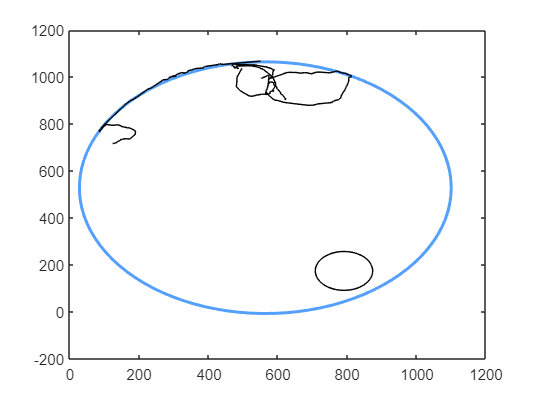

trialnumber = 3

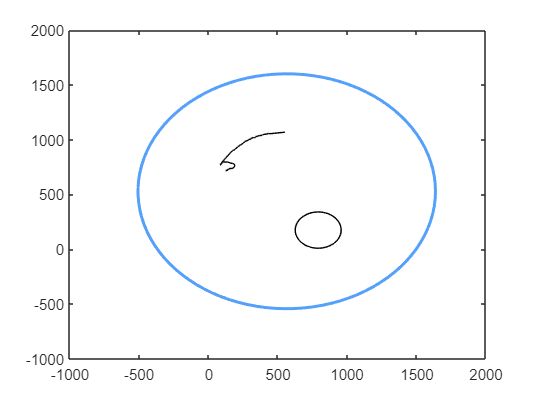

    plot(centre_xcorrected9sec, centre_ycorrected9sec, 'k')
    hold on 

## Save the entire workspace as a mat file

Ensure the matlab file is saved in the proper folder and named correctly

uisave